# ME 535 Assignment 9 - Fall 2018

# Debabrata Auddya 

**Ex. 6.12 — Revolution**

**1. Create a NURBS represented revolved surface.**

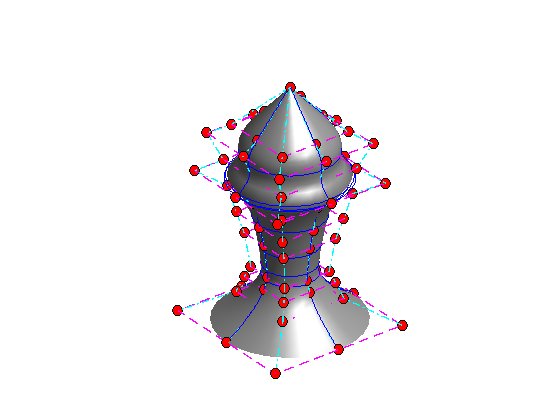

% Copyright: Xiaoping Qian @ UW-Madison
close all; clear all;

% profile 1
P = [ 0 0 0  1;
      5 0 0  1;
      5 0 5  1;
      0 0 5  1;];  % curve in x-z plane
knots = [0 0 0 0 1 1 1 1];
order = 4;


% profile 2
 P = [0 0 0 1;
     7 0 -8 1;
     10 0 -10 1;
     8 0 -15 1;
     11.5 0 -17.5 1;
     7.5 0 -20 1;
     6.5 0 -25 1;
     5.5 0 -29 1;
     4.7 0 -35.5 1;
     5.5 0 -37.5 1;
     6.5 0 -40.5 1;
     13.5 0 -45 1;];
knots = [0 0 0 0 0.333 0.47 0.48 0.49 0.54 0.59 0.62 0.666 1 1 1 1];
 
 
%do plot of control polygon
Q = bsplineCurve(P, order, knots, 50);
plot3(P(:,1),P(:,2), P(:,3),'r-s');
hold on;
plot3(Q(:,1),Q(:,2), Q(:,3),'b','linewidth',2);
axis equal;
%print('-dpdf','-painters','revolution0.pdf')

P0 = P;  % curve CPs
P1 = P0(:,1:4)+P(:,1)*[0 1 0 0]; P1(:,4) = P(:,4).*sqrt(2)/2; % offset CPs
P2 = P1(:,1:4)+P(:,1)*[-1 0 0 0];P2(:,4) = P(:,4);  % offset CPs
P3 = P2(:,1:4)+P(:,1)*[-1 0 0 0]; P3(:,4) = P(:,4)*sqrt(2)/2;
P4 = P3(:,1:4)+P(:,1)*[0  -1 0 0]; P4(:,4) = P(:,4); % offset CPs
P5 = P4(:,1:4)+P(:,1)*[ 0 -1 0 0]; P5(:,4) = P(:,4)*sqrt(2)/2;
P6 = P5(:,1:4)+P(:,1)*[1 0 0 0]; P6(:,4) = P(:,4); % offset CPs
P7 = P6(:,1:4)+P(:,1)*[1 0 0 0]; P7(:,4) = P(:,4)*sqrt(2)/2;
P8 = P7(:,1:4)+P(:,1)*[0  1 0 0]; P8(:,4) = P(:,4); % offset CPs

CPs = [P0; P1; P2; P3; P4; P5; P6; P7;P8];  % v first
knots_u = [0 0 0 1 1 2 2 3 3 4 4 4]/4.;
knots_v = knots;
k1 = 3;
k2 = order;
ncp_u = 9;
ncp_v = size(P,1);

cph=[CPs(:,1:3).*CPs(:,4), CPs(:,4)]; % turn into homogneous coorinates
tCP = reshape(cph',[4,ncp_v,ncp_u]);
CPs_d3 = permute(tCP,[1,3,2]); % change it to u first by switching 3rd dimension w/ 2nd dimension

nrbs.type   = 'Surface';
nrbs.number = [ncp_u, ncp_v];
nrbs.coefs = CPs_d3;  % CPs in homogeneous coordinates
nrbs.knots = {knots_u knots_v};
nrbs.order = [k1 k2];
    
plotNrbs(nrbs); 

%print('-dpdf','-painters','revolution1.pdf')

nrbs_Spink.form='B-NURBS';
nrbs_Spink.dim = 4

nrbs_Spink = struct with fields:
    form: 'B-NURBS'
     dim: 4


nrbs_Spink.number = [ncp_u, ncp_v];
tCP = reshape(CPs',[4,ncp_v,ncp_u]);
CPs_d3 = permute(tCP,[1,3,2]); % change it to u first by switching 3rd dimension w/ 2nd dimension
nrbs_Spink.coefs = CPs_d3;  % CPs in Euclidean coordinates
nrbs_Spink.knots = {knots_u knots_v};
nrbs_Spink.order = [k1 k2];
NrbsSrf2IGES(nrbs_Spink,'revolutionChess.igs','./');

ans = 'Finished Export to IGES'

**2. Export the surface into an IGES file.**

disp('Igs file exported and named as revolutionChess.igs')

Igs file exported and named as revolutionChess.igs


**3. Import the IGES file into a CAD software and render the surface.**

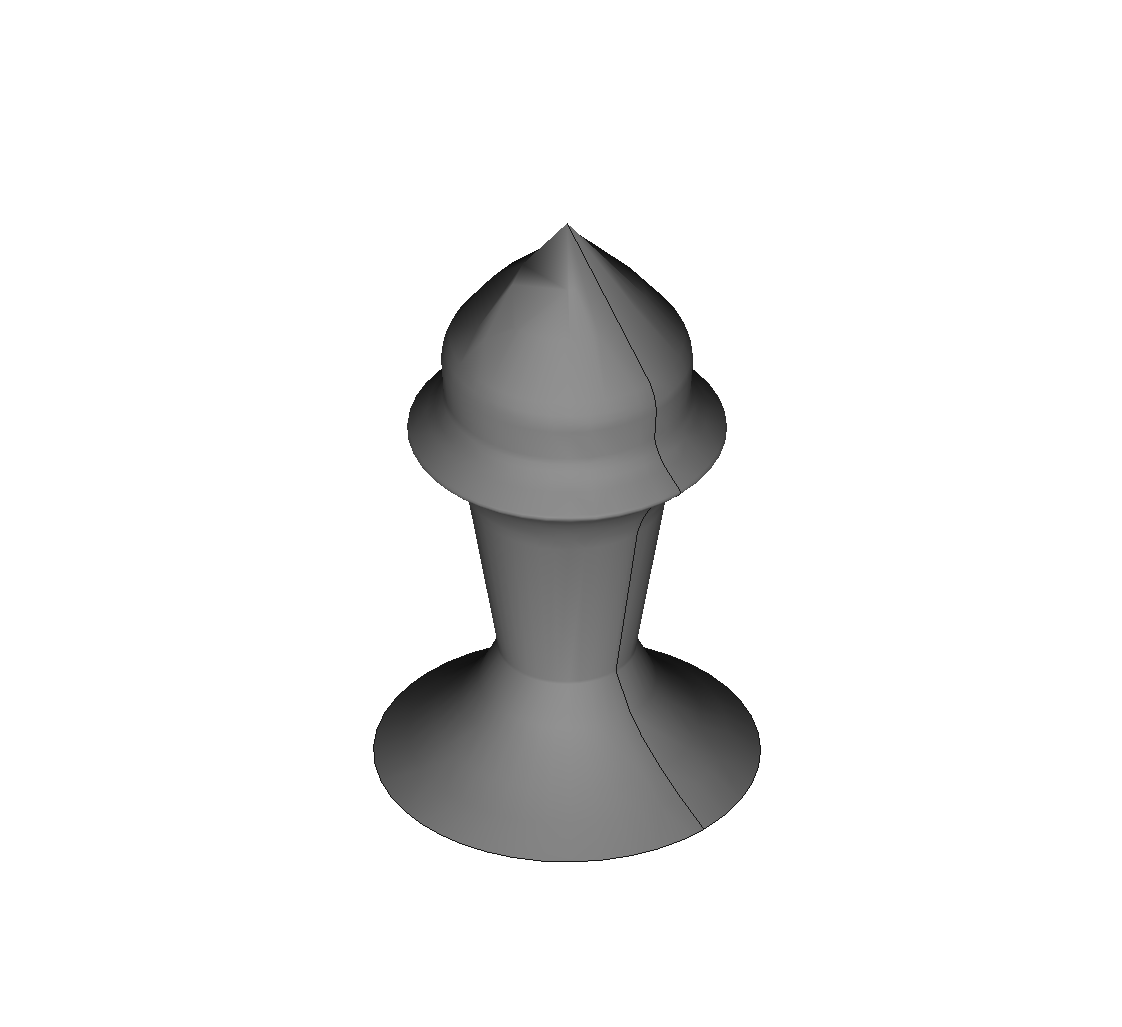

figure(2)
image1 = imread('image1.png');
imshow(image1)

**Ex. 6.13 — Sweeping**

**1. Create a NURBS represented translationally sweeping surface.**

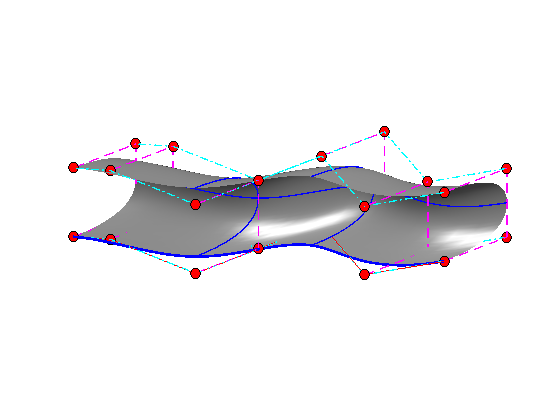

% Copyright: Xiaoping Qian @ UW-Madison
close all; clear;

% profile 1
P = [ 0 0 0  1;
      5 0 0  1;
      5 0 5  1;
      0 0 5  1;];  % curve in x-z plane
knots = [0 0 0 0 1 1 1 1];
order = 4;



% profile 2
P = [25 5 0 1;
     10 10 0 1;
     15 30 0 1;
     -15 30 0 1;
     -20 50 0 1;
     -25 55 0 1];
knots = [0 0 0 0 0.333 0.666 1 1 1 1];

P2= [0 0 0 1;
    15 0 0 1;
    15 0 15 1;
    0 0 15 1];
 

%do plot of control polygon
Q = bsplineCurve(P, order, knots, 50);
plot3(P(:,1),P(:,2), P(:,3),'r-s');
hold on;
plot3(Q(:,1),Q(:,2), Q(:,3),'b','linewidth',2);
axis equal;
%print('-dpdf','-painters','revolution0.pdf')

P0 = P;  % curve CPs
CPs=[];
for i=1:size(P2,1)
    tCP=P(:,1:3)+P2(i,1:3);
    tCP(:,4)= P(:,4)*P2(i,4);
    CPs=[CPs;tCP];
end    
%     
%     P1()=P0(:,1:3)+P2(i,1:3)
%     P1
% 
%     
% end

    

% P1 = P0(:,1:4)+P(:,1)*[0 1 0 0]; P1(:,4) = P(:,4).*sqrt(2)/2; % offset CPs
% P2 = P1(:,1:4)+P(:,1)*[-1 0 0 0];P2(:,4) = P(:,4);  % offset CPs
% P3 = P2(:,1:4)+P(:,1)*[-1 0 0 0]; P3(:,4) = P(:,4)*sqrt(2)/2;
% P4 = P3(:,1:4)+P(:,1)*[0  -1 0 0]; P4(:,4) = P(:,4); % offset CPs
% P5 = P4(:,1:4)+P(:,1)*[ 0 -1 0 0]; P5(:,4) = P(:,4)*sqrt(2)/2;
% P6 = P5(:,1:4)+P(:,1)*[1 0 0 0]; P6(:,4) = P(:,4); % offset CPs
% P7 = P6(:,1:4)+P(:,1)*[1 0 0 0]; P7(:,4) = P(:,4)*sqrt(2)/2;
% P8 = P7(:,1:4)+P(:,1)*[0  1 0 0]; P8(:,4) = P(:,4); % offset CPs

% CPs = [P0; P1; P2; P3; P4; P5; P6; P7;P8];  % v first
knots_u = [0 0 0 4 8 8 8]/8.;
knots_v = knots;
k1 = 3;
k2 = order;
ncp_u = size(P2,1);
ncp_v = size(P,1);

cph=[CPs(:,1:3).*CPs(:,4), CPs(:,4)]; % turn into homogneous coorinates
tCP = reshape(cph',[4,ncp_v,ncp_u]);
CPs_d3 = permute(tCP,[1,3,2]); % change it to u first by switching 3rd dimension w/ 2nd dimension

nrbs.type   = 'Surface';
nrbs.number = [ncp_u, ncp_v];
nrbs.coefs = CPs_d3;  % CPs in homogeneous coordinates
nrbs.knots = {knots_u knots_v};
nrbs.order = [k1 k2];
    
plotNrbs(nrbs); 

%print('-dpdf','-painters','revolution1.pdf')

nrbs_Spink.form='B-NURBS';
nrbs_Spink.dim = 4

nrbs_Spink = struct with fields:
    form: 'B-NURBS'
     dim: 4


nrbs_Spink.number = [ncp_u, ncp_v];
tCP = reshape(CPs',[4,ncp_v,ncp_u]);
CPs_d3 = permute(tCP,[1,3,2]); % change it to u first by switching 3rd dimension w/ 2nd dimension
nrbs_Spink.coefs = CPs_d3;  % CPs in Euclidean coordinates
nrbs_Spink.knots = {knots_u knots_v};
nrbs_Spink.order = [k1 k2];
NrbsSrf2IGES(nrbs_Spink,'sweep.igs','./')

ans = 'Finished Export to IGES'

**2. Export the surface into an IGES file.**

disp('Igs file exported and named as sweep.igs')

Igs file exported and named as sweep.igs


**3. Import the IGES file into a CAD software and render the surface.**

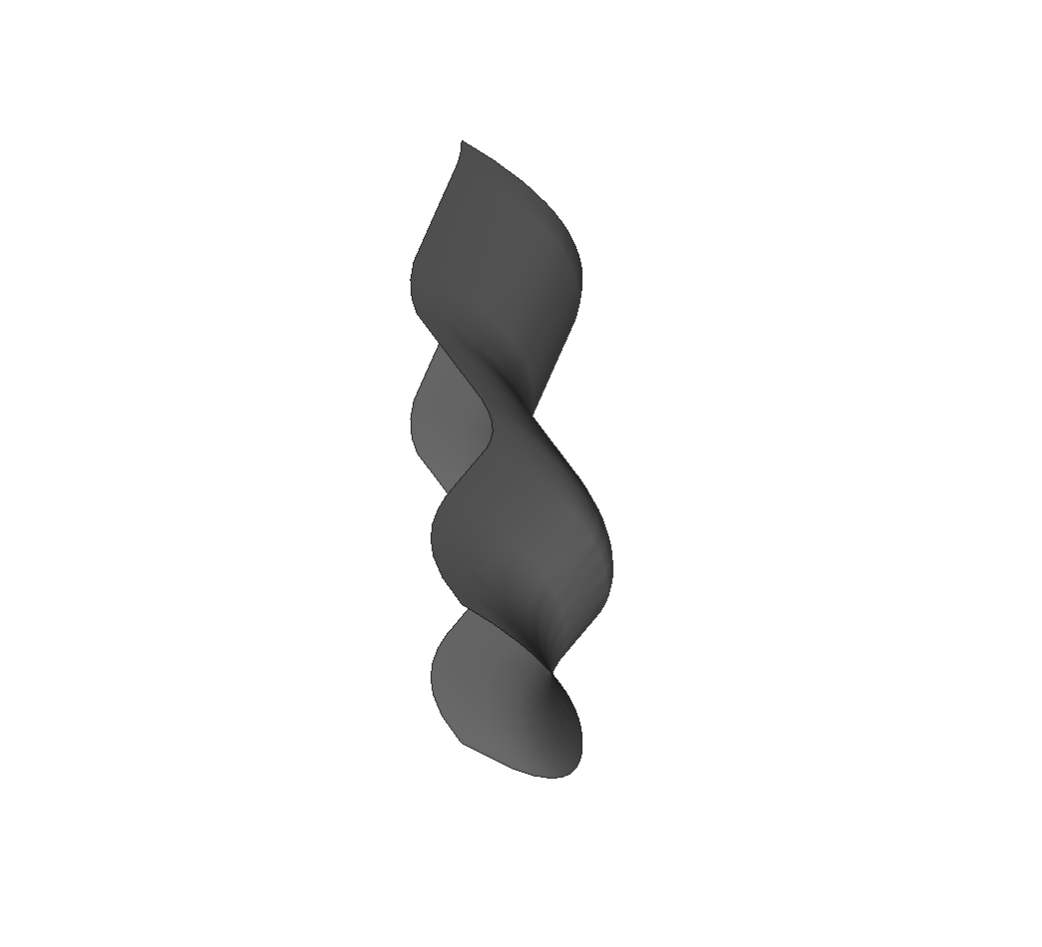

figure(3)
image2 = imread('image2.png');
imshow(image2)